close all
clear
%---setting
expri='H12test08';
infile = ['wrfout_d01_',expri];
%infile = 'testncks';
qr = ncread(infile,'QRAIN');  %qr=qr*1000;
qv = ncread(infile,'QVAPOR');  %qr=qr*1000;
%hgt = ncread(infile,'HGT');
pb = ncread(infile,'PB'); p = ncread(infile,'P');
[nz]=size(qr,3);
P=(pb+p); dP=P(:,:,1:nz-1,:)-P(:,:,2:nz,:);

tpw= dP.*( (qv(:,:,2:nz,:)+qv(:,:,1:nz-1,:)).*0.5 ) ;
TPW=squeeze(sum(tpw,3)./9.81);


ti=1; %zi=3;
plotvar=TPW(:,:,ti)'; %plotvar(plotvar<0.001)=NaN;
figure('Position',[100 100 600 400]);
  contourf(plotvar,20,'linestyle','none')
  
  %hold on; contour(hgt(:,:,1)',[100 100],'color',[0 0 0],'Linewidth',1);

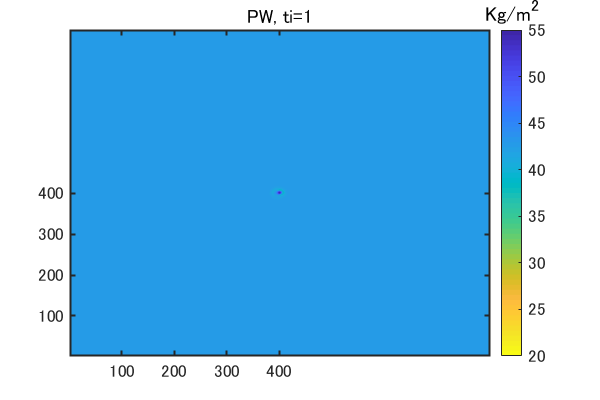

  
  title(['PW, ti=',num2str(ti)],'FontSize',20)
  
  set(gca,'fontsize',13,'linewidth',1.5,'Xtick',50:50:200,'Xticklabel',100:100:400 ...
        ,'ytick',50:50:200,'Yticklabel',100:100:400)
    
        
  cmap=flipud(parula); %cmap(1,:)=[1 1 1];
  colormap(cmap)
  hc=colorbar; set(hc,'fontsize',13)
  title(hc,'Kg/m^2','FontSize',15)
  %caxis([0 90])
  caxis([20 55])
  
  filename=[expri,'_TPW'];
  %print('-dpng',[filename,'.png'])

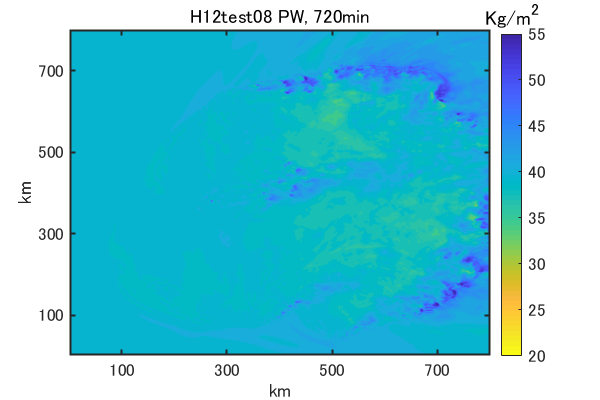

%zi=3;
varinam='TPWqv';
%eval(['variplot=double(permute(',varinam,',[2 1 3]));']);
eval('variplot=double(permute(TPW,[2 1 3]));');
filename=[expri,'_gif_',varinam,'.gif'];
h=figure('Position',[100 100 600 400],'color','w');

n=0;
for ti=2:48
  n=n+1; 
  %plotvar=variplot(:,:,zi,ti);
  plotvar=variplot(:,:,ti); %plotvar(plotvar<0.001)=NaN;
  [~, hp]=contourf(plotvar,20);   set(hp,'linestyle','none');
  %---plot height
  %hold on; contour(hgt(:,:,1)',[100 100],'color',[0 0 0],'Linewidth',1);
  
  cmap=flipud(parula); %cmap(1,:)=[1 1 1];
  colormap(cmap)
  hc=colorbar; set(hc,'fontsize',13)
  title(hc,'Kg/m^2','FontSize',15)
  %caxis([0 90])
  caxis([20 55])
  
  set(gca,'fontsize',13,'linewidth',1.5,'Xtick',50:100:400,'Xticklabel',100:200:800 ...
        ,'ytick',50:100:400,'Yticklabel',100:200:800)
  xlabel('km','fontsize',13);   ylabel('km','fontsize',13);
        
 % title(['Rain wanter level',num2str(zi),', ti=',num2str(ti)],'FontSize',20)
  title([expri,' PW, ',num2str(ti*15),'min'],'FontSize',20)

  frame=getframe(h);  im=frame2im(frame);
  [imind, cm]=rgb2ind(im,256);
  if n == 1 
    imwrite(imind,cm,filename,'gif','Loopcount',Inf,'DelayTime',0.2); 
  else 
    imwrite(imind,cm,filename,'gif','WriteMode','append'); 
  end 
end

%%


